%Purpose:
    %Econ 525-Spring2019
%Note:
    %This m-file is dependent upon S&P_Top5.xlsx.
%Author:
    %Malik Jabati — 21Feb2019
    %UNC Honor Pledge: I certify that no unauthorized assistance has been received or given in the completion of this work.
%Assumptions:
    % Used daily HPY log returns
    % Used 50 epochs to train neural network, in the interest of speed and
    % flexibility for the grader
    

## Load in data

%HouseKeeping
    clear all; close all; clc
    
    %I went through all the data, and it was clean. There were no zeros and no negatives.
    [num,txt,raw] = xlsread('S&P_Top5.xlsx','Sheet1');
    
    %Prepare the data
    assets = txt(1,2:end);
    returns = diff(log(num))*100; %convert to percentage returns
    dates = txt(3:end,1);
    T = length(returns); %Count observations
    
    %Partition the data into training and evaluation
    numTimeStepsTrain = floor(0.9*T);
    dataTrain = returns(1:numTimeStepsTrain,:);
    dataTest = returns(numTimeStepsTrain+1:end,:);
    
    %Standardize the data for LTSM model
    mu = mean(dataTrain);
    sig = std(dataTrain);
    dataTrainStandardized = (dataTrain - mu) ./ sig;
    

## 1.a Conduct a one day ahead forecast with an ARMA(1,1) model for each individual asset.


    model1 = arima(1,0,1);

    MSFT_mdl = estimate(model1,dataTrain(:,1));

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.056274       0.60243        0.093411     0.92558
    AR{1}        0.19464        8.6613        0.022472     0.98207
    MA{1}       -0.19212        8.6663       -0.022169     0.98231
    Variance      2.0912      0.046823          44.661           0



    AAPL_mdl = estimate(model1,dataTrain(:,2));

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.096674       0.10831        0.89254           0.3721
    AR{1}       -0.89058      0.043624        -20.415       1.2348e-92
    MA{1}        0.92293      0.038745         23.821      2.0396e-125
    Variance      2.1681       0.07282         29.773      8.7895e-195



    AMZN_mdl = estimate(model1,dataTrain(:,3));

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant     0.18766       0.12093          1.5518     0.12071
    AR{1}       -0.10571        0.6621        -0.15966     0.87315
    MA{1}        0.15636       0.65511         0.23867     0.81136
    Variance      3.1515      0.070772           44.53           0



    BRKB_mdl = estimate(model1,dataTrain(:,4));

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.013139      0.016242        0.80898          0.41853
    AR{1}        0.50102       0.19389         2.5841        0.0097637
    MA{1}       -0.59454       0.17776        -3.3446       0.00082415
    Variance     0.88646      0.035211         25.176      7.3637e-140



    FB_mdl = estimate(model1,dataTrain(:,5));  

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue 
                _________    _____________    __________    _______

    Constant      0.12246      0.094582          1.2947     0.19542
    AR{1}       -0.044448       0.65835       -0.067514     0.94617
    MA{1}        0.096301        0.6595         0.14602     0.88391
    Variance       2.3504      0.051796          45.378           0



   
    %Conduct one-day ahead forecast
    MSFT_fcst1 = forecast(MSFT_mdl,1,'Y0',dataTrain(:,1));
    AAPL_fcst1 = forecast(AAPL_mdl,1,'Y0',dataTrain(:,2));
    AMZN_fcst1 = forecast(AMZN_mdl,1,'Y0',dataTrain(:,3));
    BRKB_fcst1 = forecast(BRKB_mdl,1,'Y0',dataTrain(:,4));
    FB_fcst1 = forecast(FB_mdl,1,'Y0',dataTrain(:,5));
    
    
    

## 1.b Conduct a one day ahead forecast with an LSTM model for each individual asset.

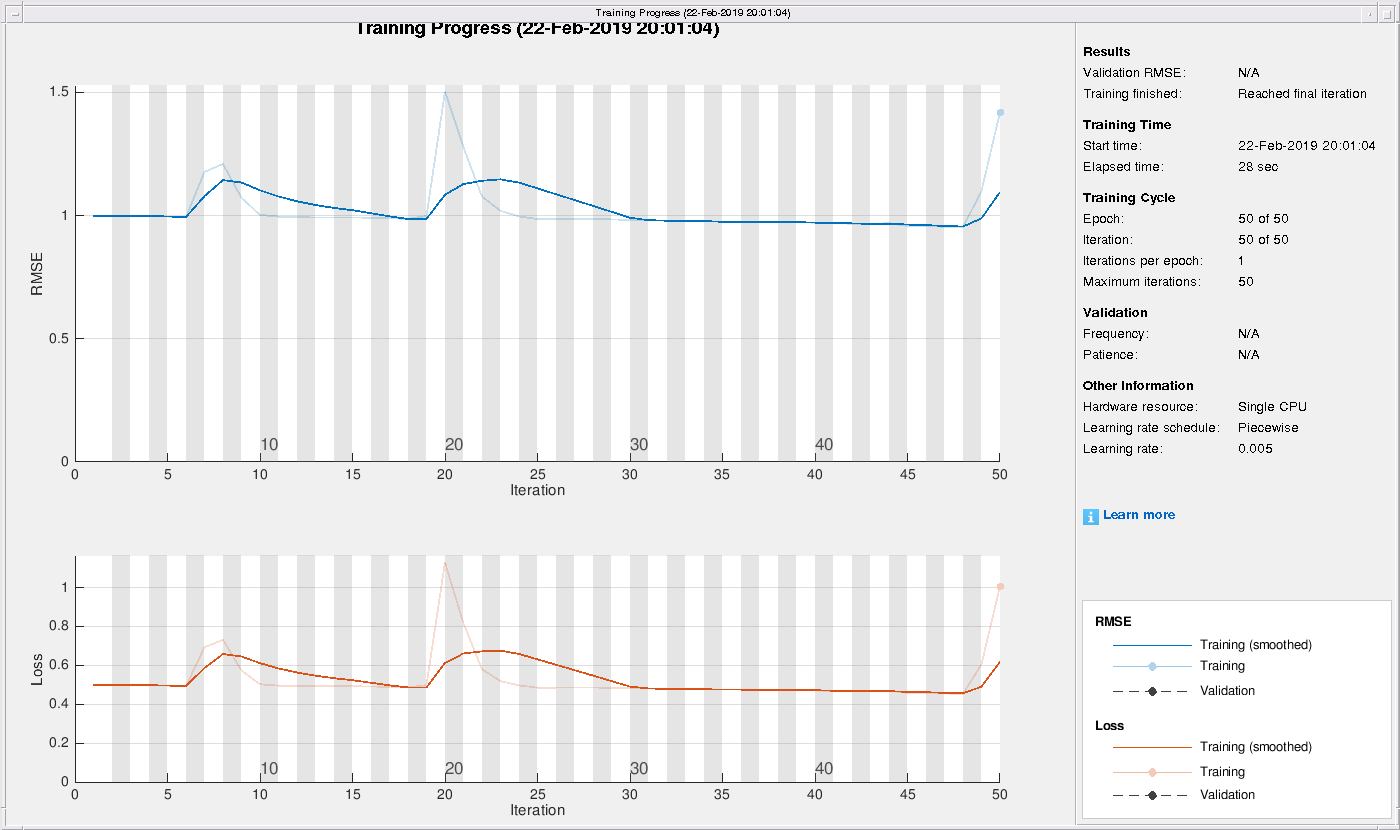

    
    %Use the time t to predict t+1
    XTrain = dataTrainStandardized(1:end-1,:); %Lagged values of the data for predictors
    YTrain = dataTrainStandardized(2:end,:);
    
    %Generate the regression network
    numFeatures = 1;
    numResponses = 1;
    numHiddenUnits = 200;
    %Define the options for the LSTM network
    layers = [ ...
        sequenceInputLayer(numFeatures)
        lstmLayer(numHiddenUnits)
        fullyConnectedLayer(numResponses)
        regressionLayer];
    
    options = trainingOptions('adam', ...
        'MaxEpochs',50, ...
        'GradientThreshold',1, ...
        'InitialLearnRate',0.005, ...
        'LearnRateSchedule','piecewise', ...
        'LearnRateDropPeriod',125, ...
        'LearnRateDropFactor',0.2, ...
        'Verbose',0, ...
        'Plots','training-progress');
    
    %Train the network
    
    MSFT_net = trainNetwork(XTrain(:,1)',YTrain(:,1)',layers,options);
    AAPL_net = trainNetwork(XTrain(:,2)',YTrain(:,2)',layers,options);
    AMZN_net = trainNetwork(XTrain(:,3)',YTrain(:,3)',layers,options);
    BRKB_net = trainNetwork(XTrain(:,4)',YTrain(:,4)',layers,options);

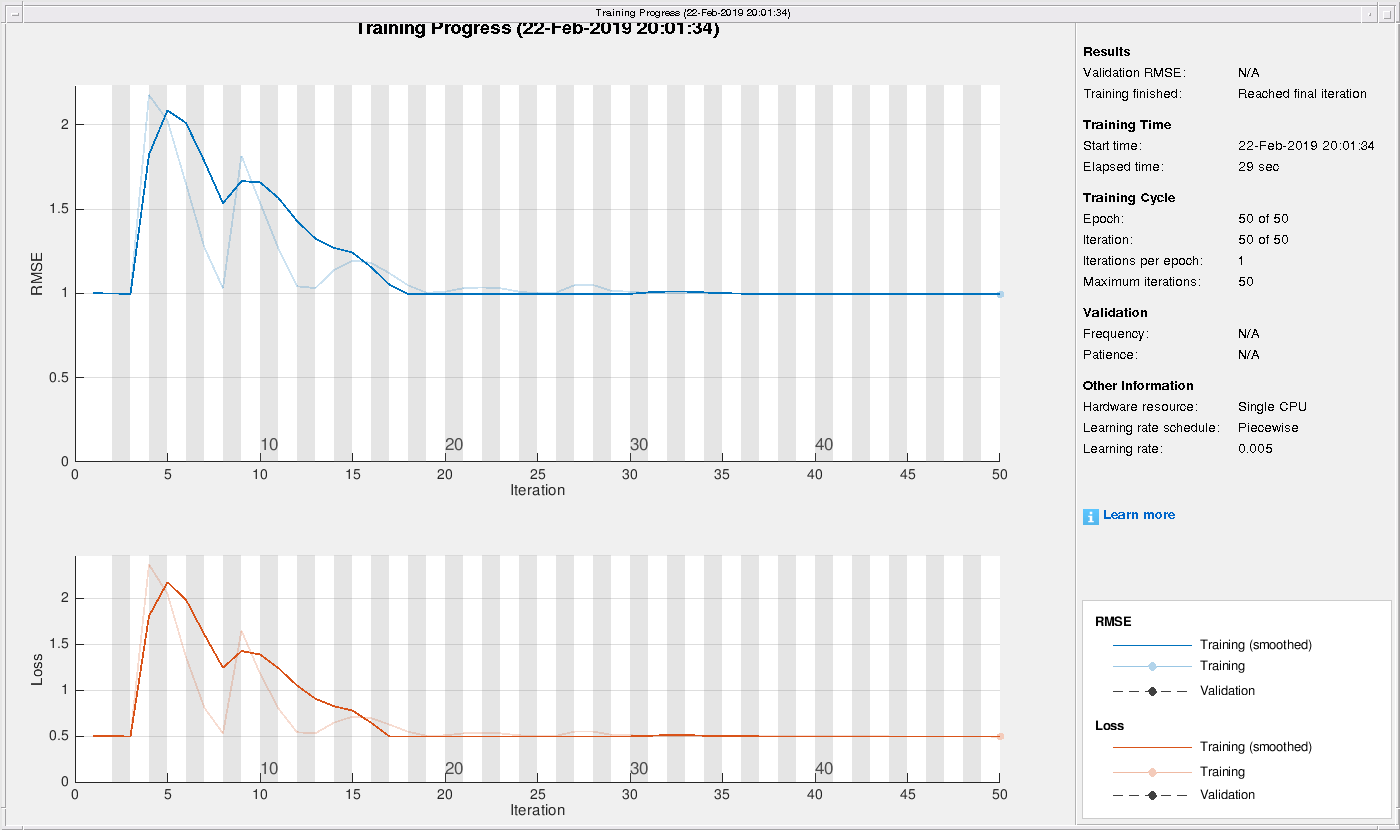

    FB_net = trainNetwork(XTrain(:,5)',YTrain(:,5)',layers,options);

    %Forecast one day ahead using LSTM model

    %Standardize
    dataTestStandardized = (dataTest - mu) ./ sig;
    XTest = dataTestStandardized(1:end-1,:);
    
    %To initialize the network state, make the first prediction using the last time step of the training response YTrain(end). 
    %Loop over the remaining predictions and input the previous prediction to predictAndUpdateState.
    
    MSFT_YPred = predict(MSFT_net,YTrain(end,1));
    AAPL_YPred = predict(AAPL_net,YTrain(end,2));
    AMZN_YPred = predict(AMZN_net,YTrain(end,3));
    BRKB_YPred = predict(BRKB_net,YTrain(end,4));
    FB_YPred = predict(FB_net,YTrain(end,5));
    
    %[MSFT_net,MSFT_YPred] = predictAndUpdateState(MSFT_net,YTrain(end,1));
    %[AAPL_net,AAPL_YPred] = predictAndUpdateState(AAPL_net,YTrain(end,2));
    %[AMZN_net,AMZN_YPred] = predictAndUpdateState(AMZN_net,YTrain(end,3));
    %[BRKB_net,BRKB_YPred] = predictAndUpdateState(BRKB_net,YTrain(end,4));
    %[FB_net,FB_YPred] = predictAndUpdateState(FB_net,YTrain(end,5));
    
    

## 1.c Repeat part a for 2 days ahead, 3 days ahead, 4 days ahead and 5 days ahead.

    
    %Conduct five-day ahead forecast using ARMA model
    
    [MSFT_fcst5, MSFT_MSE] = forecast(MSFT_mdl,5,'Y0',dataTrain(:,1));
    [AAPL_fcst5, AAPL_MSE] = forecast(AAPL_mdl,5,'Y0',dataTrain(:,2));
    [AMZN_fcst5, AMZN_MSE] = forecast(AMZN_mdl,5,'Y0',dataTrain(:,3));
    [BRKB_fcst5, BRKB_MSE] = forecast(BRKB_mdl,5,'Y0',dataTrain(:,4));
    [FB_fcst5, FB_MSE] = forecast(FB_mdl,5,'Y0',dataTrain(:,5));
    
    %MSFT_fcst5 = zeros([1,5]);
    %AAPL_fcst5 = zeros([1,5]);
    %AMZN_fcst5 = zeros([1,5]);
    %BRKB_fcst5 = zeros([1,5]);
    %FB_fcst5 = zeros([1,5]);
    
    %for i=1:5
    %    [MSFT_fcst5(i), MSFT_MSE] = forecast(MSFT_mdl,1,'Y0',dataTrain(end-(i-1),1));
    %    [AAPL_fcst5(i), AAPL_MSE] = forecast(AAPL_mdl,1,'Y0',dataTrain(end-(i-1),2));
    %    [AMZN_fcst5(i), AMZN_MSE] = forecast(AMZN_mdl,1,'Y0',dataTrain(end-(i-1),3));
    %    [BRKB_fcst5(i), BRKB_MSE] = forecast(BRKB_mdl,1,'Y0',dataTrain(end-(i-1),4));
    %    [FB_fcst5(i), FB_MSE] = forecast(FB_mdl,1,'Y0',dataTrain(end-(i-1),5));
    %end
    

## 1.d Repeat part b for 2 days ahead, 3 days ahead, 4 days ahead and 5 days ahead.

    
    %Predict five days ahead using static LSTM model
    
    %Create vectors to store predicted values
    MSFT_YPred5 = zeros([1,5]);
    AAPL_YPred5 = zeros([1,5]);
    AMZN_YPred5 = zeros([1,5]);
    BRKB_YPred5 = zeros([1,5]);
    FB_YPred5 = zeros([1,5]);
    
    for i=1:5 %five steps ahead
        MSFT_YPred5(i) = predict(MSFT_net,YTrain(end-(i-1),1));
        AAPL_YPred5(i) = predict(AAPL_net,YTrain(end-(i-1),2));
        AMZN_YPred5(i) = predict(AMZN_net,YTrain(end-(i-1),3));
        BRKB_YPred5(i) = predict(BRKB_net,YTrain(end-(i-1),4));
        FB_YPred5(i) = predict(FB_net,YTrain(end-(i-1),5));
    end
    
    %for i=1:5 %five steps ahead
    %    [MSFT_net,MSFT_YPred5(i)] = predictAndUpdateState(MSFT_net,YTrain(end-(i-1),1));
    %    [AAPL_net,AAPL_YPred5(i)] = predictAndUpdateState(AAPL_net,YTrain(end-(i-1),2));
    %    [AMZN_net,AMZN_YPred5(i)] = predictAndUpdateState(AMZN_net,YTrain(end-(i-1),3));
    %    [BRKB_net,BRKB_YPred5(i)] = predictAndUpdateState(BRKB_net,YTrain(end-(i-1),4));
    %    [FB_net,FB_YPred5(i)] = predictAndUpdateState(FB_net,YTrain(end-(i-1),5));
    % end
    
    
    

## 1.e Repeat part c, but now with a dynamic forecasting structure.

    
    %Conduct five-day ahead dynamic forecast using ARMA model
    
    %Create vectors for dynamic forecasts, putting final training value
    %into first position
    
    MSFT_fcst5d = zeros([1,5]);
    AAPL_fcst5d = zeros([1,5]);
    AMZN_fcst5d = zeros([1,5]);
    BRKB_fcst5d = zeros([1,5]);
    FB_fcst5d = zeros([1,5]);
    
    %Initialize first values
    
    MSFT_fcst5d(1) = MSFT_fcst1;
    AAPL_fcst5d(1) = AAPL_fcst1;
    AMZN_fcst5d(1) = AMZN_fcst1;
    BRKB_fcst5d(1) = BRKB_fcst1;
    FB_fcst5d(1) = FB_fcst1;
    
    dataTrainMSFT = [dataTrain(:,1); MSFT_fcst1];
    dataTrainAAPL = [dataTrain(:,2); AAPL_fcst1];
    dataTrainAMZN = [dataTrain(:,3); AMZN_fcst1];
    dataTrainBRKB = [dataTrain(:,4); BRKB_fcst1];
    dataTrainFB = [dataTrain(:,5); FB_fcst1];
    
    MSFT_mdl = estimate(model1,dataTrainMSFT);

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.056286       0.60148         0.09358     0.92544
    AR{1}        0.19445        8.6479        0.022485     0.98206
    MA{1}       -0.19193        8.6529       -0.022181      0.9823
    Variance      2.0881      0.046683          44.729           0



    AAPL_mdl = estimate(model1,dataTrainAAPL);

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.096674       0.10815        0.89385           0.3714
    AR{1}       -0.89058      0.043559        -20.445       6.6239e-93
    MA{1}        0.92293      0.038687         23.856      8.7353e-126
    Variance      2.1649      0.072596         29.821      2.0969e-195



    AMZN_mdl = estimate(model1,dataTrainAMZN);    

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant     0.18766       0.12076          1.5541     0.12017
    AR{1}       -0.10569       0.66113        -0.15986     0.87299
    MA{1}        0.15633       0.65415         0.23898     0.81112
    Variance      3.1469      0.070559          44.599           0



    BRKB_mdl = estimate(model1,dataTrainBRKB);

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.013139      0.016218        0.81017          0.41784
    AR{1}        0.50102        0.1936         2.5879        0.0096558
    MA{1}       -0.59454        0.1775        -3.3495       0.00080955
    Variance     0.88516        0.0351         25.218      2.5484e-140



    FB_mdl = estimate(model1,dataTrainFB);      

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue 
                _________    _____________    __________    _______

    Constant      0.12246      0.094443          1.2966     0.19476
    AR{1}       -0.044444       0.65738       -0.067608      0.9461
    MA{1}        0.096298       0.65853         0.14623     0.88374
    Variance        2.347      0.051641          45.448           0




    %Forecast i-step ahead, append this result to training data, and
    %re-estimate model. Repeat until you reach five steps ahead
    for i=2:5 %five steps ahead
              
        [MSFT_fcst5d(i), MSFT_MSEd] = forecast(MSFT_mdl,1,'Y0',dataTrainMSFT);
        [AAPL_fcst5d(i), AAPL_MSEd] = forecast(AAPL_mdl,1,'Y0',dataTrainAAPL);
        [AMZN_fcst5d(i), AMZN_MSEd] = forecast(AMZN_mdl,1,'Y0',dataTrainAMZN);
        [BRKB_fcst5d(i), BRKB_MSEd] = forecast(BRKB_mdl,1,'Y0',dataTrainBRKB);
        [FB_fcst5d(i), FB_MSEd] = forecast(FB_mdl,1,'Y0',dataTrainFB);
        
        dataTrainMSFT = [dataTrainMSFT; MSFT_fcst5d(i)];
        dataTrainAAPL = [dataTrainAAPL; AAPL_fcst5d(i)];
        dataTrainAMZN = [dataTrainAMZN; AMZN_fcst5d(i)];
        dataTrainBRKB = [dataTrainBRKB; BRKB_fcst5d(i)];
        dataTrainFB = [dataTrainFB; FB_fcst5d(i)];
        
        MSFT_mdl = estimate(model1,dataTrainMSFT);
        AAPL_mdl = estimate(model1,dataTrainAAPL);
        AMZN_mdl = estimate(model1,dataTrainAMZN);    
        BRKB_mdl = estimate(model1,dataTrainBRKB);
        FB_mdl = estimate(model1,dataTrainFB);  
    end

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.056283       0.60082        0.093678     0.92536
    AR{1}         0.1945        8.6383        0.022516     0.98204
    MA{1}       -0.19198        8.6433       -0.022211     0.98228
    Variance       2.085      0.046543          44.798           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.069788        0.10947       0.63754          0.52377
    AR{1}       -0.97333      0.0047039       -206.92                0
    MA{1}        0.99258      0.0060079        165.21                0
    Variance      2.1563       0.072899        29.579      2.7529e-192



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic    PValue 
                _______    _____________    __________    _______

    Constant    0.18766       0.12058          1.5564     0.11962
    AR{1}       -0.1057       0.66016        -0.16011     0.87279
    MA{1}       0.15634       0.65319         0.23935     0.81083
    Variance     3.1422      0.070348          44.667           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.013139      0.016194        0.81136          0.41716
    AR{1}        0.50102       0.19331         2.5918        0.0095488
    MA{1}       -0.59454       0.17724        -3.3545       0.00079517
    Variance     0.88386      0.034991          25.26      8.8047e-141



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue 
                _________    _____________    __________    _______

    Constant      0.12246      0.094304          1.2985     0.19411
    AR{1}       -0.044445       0.65642       -0.067709     0.94602
    MA{1}        0.096298       0.65757         0.14645     0.88357
    Variance       2.3435      0.051486          45.517           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.056293       0.59964        0.093877     0.92521
    AR{1}        0.19434        8.6218         0.02254     0.98202
    MA{1}       -0.19181        8.6268       -0.022234     0.98226
    Variance       2.082      0.046404          44.866           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.069789         0.1093       0.63848          0.52316
    AR{1}       -0.97333       0.004697       -207.22                0
    MA{1}        0.99258      0.0059991        165.46                0
    Variance      2.1532       0.072675        29.627      6.7024e-193



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic    PValue 
                _______    _____________    __________    _______

    Constant    0.18767        0.1204          1.5587     0.11908
    AR{1}       -0.1057        0.6592        -0.16034     0.87261
    MA{1}       0.15634       0.65223          0.2397     0.81057
    Variance     3.1376      0.070137          44.736           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.013139       0.01617        0.81256          0.41647
    AR{1}        0.50102       0.19303         2.5956        0.0094436
    MA{1}       -0.59454       0.17698        -3.3594       0.00078113
    Variance     0.88257      0.034881         25.302      3.0375e-141



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant     0.12246      0.094166          1.3004     0.19345
    AR{1}       -0.04445       0.65545       -0.067817     0.94593
    MA{1}       0.096304        0.6566         0.14667     0.88339
    Variance      2.3401      0.051332          45.587           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.056276       0.59886        0.093973     0.92513
    AR{1}        0.19459        8.6101        0.022601     0.98197
    MA{1}       -0.19208        8.6151       -0.022295     0.98221
    Variance      2.0789      0.046265          44.935           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.069788        0.10914       0.63941          0.52256
    AR{1}       -0.97333      0.0046901       -207.53                0
    MA{1}        0.99258      0.0059903         165.7                0
    Variance        2.15       0.072452        29.675      1.6288e-193



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant     0.18766       0.12023          1.5609     0.11854
    AR{1}       -0.10569       0.65823        -0.16057     0.87243
    MA{1}        0.15634       0.65128         0.24005     0.81029
    Variance       3.133      0.069927          44.804           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.013139      0.016147        0.81375          0.41579
    AR{1}        0.50102       0.19274         2.5994         0.009339
    MA{1}       -0.59454       0.17672        -3.3643       0.00076725
    Variance     0.88127      0.034772         25.344      1.0457e-141



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue 
                _________    _____________    __________    _______

    Constant      0.12246      0.094028          1.3023      0.1928
    AR{1}       -0.044447       0.65449       -0.067912     0.94586
    MA{1}        0.096301       0.65564         0.14688     0.88323
    Variance       2.3367      0.051179          45.657           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.056316       0.59794        0.094184     0.92496
    AR{1}        0.19401        8.5974        0.022567       0.982
    MA{1}       -0.19149        8.6024        -0.02226     0.98224
    Variance      2.0759      0.046127          45.003           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.069788        0.10898       0.64034          0.52195
    AR{1}       -0.97333      0.0046832       -207.83                0
    MA{1}        0.99258      0.0059815        165.94                0
    Variance      2.1469        0.07223        29.722      3.9487e-194



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant     0.18766       0.12005          1.5632       0.118
    AR{1}       -0.10569       0.65726        -0.16081     0.87224
    MA{1}        0.15634       0.65032          0.2404     0.81002
    Variance      3.1285      0.069719          44.872           0



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.013139      0.016123        0.81494          0.41511
    AR{1}        0.50102       0.19246         2.6032        0.0092348
    MA{1}       -0.59454       0.17646        -3.3693       0.00075353
    Variance     0.87998      0.034664         25.386      3.5929e-142



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue 
                _________    _____________    __________    _______

    Constant      0.12246      0.093891          1.3042     0.19215
    AR{1}       -0.044452       0.65353       -0.068018     0.94577
    MA{1}        0.096306       0.65468          0.1471     0.88305
    Variance       2.3332      0.051026          45.726           0



## 1.f Repeat part d, but now with a dynamic forecasting structure.

%Conduct five-day ahead dynamic forecast using LSTM model

    %Create vectors to store predicted values
    MSFT_YPred5d = zeros([1,5]);
    AAPL_YPred5d = zeros([1,5]);
    AMZN_YPred5d = zeros([1,5]);
    BRKB_YPred5d = zeros([1,5]);
    FB_YPred5d = zeros([1,5]);
    
    %Initialize first values
    [MSFT_net,MSFT_YPred5d(1)] = predictAndUpdateState(MSFT_net,YTrain(end,1));
    [AAPL_net,AAPL_YPred5d(1)] = predictAndUpdateState(AAPL_net,YTrain(end,2));
    [AMZN_net,AMZN_YPred5d(1)] = predictAndUpdateState(AMZN_net,YTrain(end,3));
    [BRKB_net,BRKB_YPred5d(1)] = predictAndUpdateState(BRKB_net,YTrain(end,4));
    [FB_net,FB_YPred5d(1)] = predictAndUpdateState(FB_net,YTrain(end,5));
    
    
    for i=2:5 %five steps ahead
        [MSFT_net,MSFT_YPred5d(i)] = predictAndUpdateState(MSFT_net,MSFT_YPred5d(i-1));
        [AAPL_net,AAPL_YPred5d(i)] = predictAndUpdateState(AAPL_net,AAPL_YPred5d(i-1));
        [AMZN_net,AMZN_YPred5d(i)] = predictAndUpdateState(AMZN_net,AMZN_YPred5d(i-1));
        [BRKB_net,BRKB_YPred5d(i)] = predictAndUpdateState(BRKB_net,BRKB_YPred5d(i-1));
        [FB_net,FB_YPred5d(i)] = predictAndUpdateState(FB_net,FB_YPred5d(i-1));
    end
    

## 2.a Create two tables

%Table 1: Static Forecast Results

    StaticVariables = {'static_1day_ARMA','static_1day_LSTM','static_2day_ARMA','static_2day_LSTM', ...
        'static_3day_ARMA','static_3day_LSTM','static_4day_ARMA','static_4day_LSTM','static_5day_ARMA','static_5day_LSTM'};

    StaticForecasts_array = zeros([5,10]);
    
    for i=1:5      
        %ARMA static forecasts
        StaticForecasts_array(1,2*(i-1)+1) = MSFT_fcst5(i);
        StaticForecasts_array(2,2*(i-1)+1) = AAPL_fcst5(i);
        StaticForecasts_array(3,2*(i-1)+1) = AMZN_fcst5(i);
        StaticForecasts_array(4,2*(i-1)+1) = BRKB_fcst5(i);
        StaticForecasts_array(5,2*(i-1)+1) = FB_fcst5(i);
        
        %LSTM static forecasts (need to unstandardize before placing in table)
        StaticForecasts_array(1,2*i) = MSFT_YPred5(i)*sig(1)+mu(1);
        StaticForecasts_array(2,2*i) = AAPL_YPred5(i)*sig(2)+mu(2);
        StaticForecasts_array(3,2*i) = AMZN_YPred5(i)*sig(3)+mu(3);
        StaticForecasts_array(4,2*i) = BRKB_YPred5(i)*sig(4)+mu(4);
        StaticForecasts_array(5,2*i) = FB_YPred5(i)*sig(5)+mu(5);
    end
    
    StaticForecasts = array2table(StaticForecasts_array,'RowNames',assets,'VariableNames',StaticVariables)

StaticForecasts = 5×10 table
             static_1day_ARMA    static_1day_LSTM    static_2day_ARMA    static_2day_LSTM    static_3day_ARMA    static_3day_LSTM    static_4day_ARMA    static_4day_LSTM    static_5day_ARMA    static_5day_LSTM
             ________________    ________________    ________________    ________________    ________________    ________________    ________________    ________________    ________________    ________________

    MSFT          0.06987             0.06997            0.069873             0.066223           0.069874            0.070677            0.069874            0.065237            0.069874        

    
%Table 2: Dynamic Forecast Results
    
    DynamicVariables = {'dyn_1day_ARMA','dyn_1day_LSTM','dyn_2day_ARMA','dyn_2day_LSTM', ...
        'dyn_3day_ARMA','dyn_3day_LSTM','dyn_4day_ARMA','dyn_4day_LSTM','dyn_5day_ARMA','dyn_5day_LSTM'};
    
    
    DynamicForecasts_array = zeros([5,10]);
    
    for i=1:5      
        %ARMA dynamic forecasts
        DynamicForecasts_array(1,2*(i-1)+1) = MSFT_fcst5d(i);
        DynamicForecasts_array(2,2*(i-1)+1) = AAPL_fcst5d(i);
        DynamicForecasts_array(3,2*(i-1)+1) = AMZN_fcst5d(i);
        DynamicForecasts_array(4,2*(i-1)+1) = BRKB_fcst5d(i);
        DynamicForecasts_array(5,2*(i-1)+1) = FB_fcst5d(i);
        
        %LSTM dynamic forecasts (need to unstandardize before placing in table)
        DynamicForecasts_array(1,2*i) = MSFT_YPred5d(i)*sig(1)+mu(1);
        DynamicForecasts_array(2,2*i) = AAPL_YPred5d(i)*sig(2)+mu(2);
        DynamicForecasts_array(3,2*i) = AMZN_YPred5d(i)*sig(3)+mu(3);
        DynamicForecasts_array(4,2*i) = BRKB_YPred5d(i)*sig(4)+mu(4);
        DynamicForecasts_array(5,2*i) = FB_YPred5d(i)*sig(5)+mu(5);
    end    
        
        
    DynamicForecasts = array2table(DynamicForecasts_array,'RowNames',assets,'VariableNames',DynamicVariables)

DynamicForecasts = 5×10 table
             dyn_1day_ARMA    dyn_1day_LSTM    dyn_2day_ARMA    dyn_2day_LSTM    dyn_3day_ARMA    dyn_3day_LSTM    dyn_4day_ARMA    dyn_4day_LSTM    dyn_5day_ARMA    dyn_5day_LSTM
             _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    MSFT         0.06987          0.06997         0.069872         0.093541         0.069873          0.11431         0.069871          0.12886        0.069873           0.13544  
    AAPL       -0.027146         0.053063          0.12

## 2.b Comment on the two tables. Be sure to discuss if the static and dynamic forecasts look very different for either of the models.


%For the ARMA models, the static and dynamic forecasts appear to be the
%same. For the LSTM models, the static and dynamic models are different but
%the discrepancy is small. For a five-day horizon, the choice between a
%static or dynamic model does not appear to make much of a difference. This
%is likely due to the magnitude of the compounding errors still being small in the dynamic model.


## 2.c Calculate the RMSE for the static forecasts for each asset and model


    %RMSE for static ARMA models
    MSFT_RMSEa = sqrt(MSFT_MSE(5));
    AAPL_RMSEa = sqrt(AAPL_MSE(5));
    AMZN_RMSEa = sqrt(AMZN_MSE(5));
    BRKB_RMSEa = sqrt(BRKB_MSE(5));
    FB_RMSEa = sqrt(FB_MSE(5));
    
    %Compute RMSE for static LSTM models
    YTest = dataTest(1:5,:);
    
    MSFT_RMSEl = sqrt(mean((MSFT_YPred5'-YTest(:,1)).^2));
    AAPL_RMSEl = sqrt(mean((AAPL_YPred5'-YTest(:,2)).^2));
    AMZN_RMSEl = sqrt(mean((AMZN_YPred5'-YTest(:,3)).^2));
    BRKB_RMSEl = sqrt(mean((BRKB_YPred5'-YTest(:,4)).^2));
    FB_RMSEl = sqrt(mean((FB_YPred5'-YTest(:,5)).^2));
    
    

## 2.d Calculate the RMSE for the dynamic forecasts for each asset and model.


    %RMSE for dynamic ARMA models
    MSFT_RMSEad = sqrt(MSFT_MSEd);
    AAPL_RMSEad = sqrt(AAPL_MSEd);
    AMZN_RMSEad = sqrt(AMZN_MSEd);
    BRKB_RMSEad = sqrt(BRKB_MSEd);
    FB_RMSEad = sqrt(FB_MSEd);
    
    %Compute RMSE for dynamic LSTM models
    YTest = dataTest(1:5,:);
    
    MSFT_RMSEld = sqrt(mean((MSFT_YPred5d'-YTest(:,1)).^2));
    AAPL_RMSEld = sqrt(mean((AAPL_YPred5d'-YTest(:,2)).^2));
    AMZN_RMSEld = sqrt(mean((AMZN_YPred5d'-YTest(:,3)).^2));
    BRKB_RMSEld = sqrt(mean((BRKB_YPred5d'-YTest(:,4)).^2));
    FB_RMSEld = sqrt(mean((FB_YPred5d'-YTest(:,5)).^2));
    

## 2.e Create a table where you present the RMSE’s calculated above with asset names as the row labels.


    RMSEForecasts_array = zeros([5,4]);
    
    %Static RMSE ARMA
    RMSEForecasts_array(1,1) = MSFT_RMSEa;
    RMSEForecasts_array(2,1) = AAPL_RMSEa;
    RMSEForecasts_array(3,1) = AMZN_RMSEa;
    RMSEForecasts_array(4,1) = BRKB_RMSEa;
    RMSEForecasts_array(5,1) = FB_RMSEa;
    
    %Static RMSE LSTM
    RMSEForecasts_array(1,2) = MSFT_RMSEl;
    RMSEForecasts_array(2,2) = AAPL_RMSEl;
    RMSEForecasts_array(3,2) = AMZN_RMSEl;
    RMSEForecasts_array(4,2) = BRKB_RMSEl;
    RMSEForecasts_array(5,2) = FB_RMSEl;    
    
    %Dynamic RMSE ARMA
    RMSEForecasts_array(1,3) = MSFT_RMSEad;
    RMSEForecasts_array(2,3) = AAPL_RMSEad;
    RMSEForecasts_array(3,3) = AMZN_RMSEad;
    RMSEForecasts_array(4,3) = BRKB_RMSEad;
    RMSEForecasts_array(5,3) = FB_RMSEad;
    
    %Dynamic RMSE LSTM
    RMSEForecasts_array(1,4) = MSFT_RMSEld;
    RMSEForecasts_array(2,4) = AAPL_RMSEld;
    RMSEForecasts_array(3,4) = AMZN_RMSEld;
    RMSEForecasts_array(4,4) = BRKB_RMSEld;
    RMSEForecasts_array(5,4) = FB_RMSEld;    
    
    RMSEForecasts = array2table(RMSEForecasts_array,'RowNames',assets,'VariableNames',{'static_RMSE_ARMA','static_RMSE_LSTM','dyn_RMSE_ARMA','dyn_RMSE_LSTM'})

RMSEForecasts = 5×4 table
             static_RMSE_ARMA    static_RMSE_LSTM    dyn_RMSE_ARMA    dyn_RMSE_LSTM
             ________________    ________________    _____________    _____________

    MSFT          1.4461             0.55407             1.4418          0.54822   
    AAPL          1.4747             0.74508             1.4663          0.76076   
    AMZN          1.7775              1.0618               1.77           1.0096   
    BRK.B        0.94698             0.62967            0.93876           0.6869   
    FB            1.5352             0.96039             1.5286           1.0213   


    
    RMSE_means = mean(table2array(RMSEForecasts))

RMSE_means =     1.4361    0.7902    1.4291    0.8054


## 2.f Comment on the above table. Be sure to discuss which model had the lowest RMSE on average, static vs dynamic accuracy, assets with high accuracy, etc...

%The static LSTM model had the lowest RMSE on average, although its RMSE was not
%much smaller than that of the dynamic LSTM model.
% 
%There did not appear to be much difference between the RMSE for the
%static and dynamic models. For ARMA, the dynamic model was slightly more
%accurate. The Berkshire Hathaway Class B (BRK.B) and Microsoft (MSFT) assets generally had the
%highest accuracy. BRK.B predictions were the most accurate among the ARMA
%models, and MSFT predictions were the most accurate among the LSTM models.
%This is likely due to the low variability of returns near the end of the
%training period and beginning of the test period.